# **CPSC 302: Assignment 7**

# Nicholas Hu

*This code makes use of *[*Spot*](http://www.cs.ubc.ca/labs/scl/spot/index.html)*, a linear operator toolbox by Ewout van den Berg and Michael P. Friedlander.*

## Question 4

**(b)**

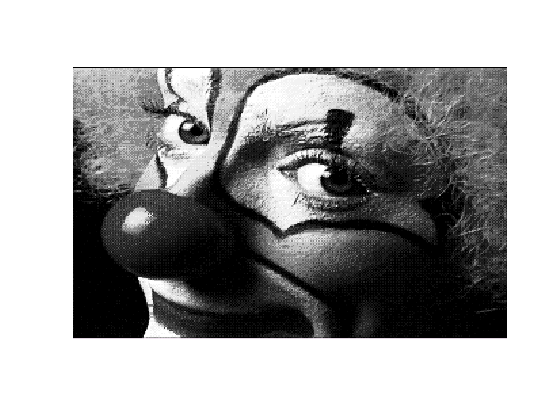

load clown
[m, n] = size(X);
N = m * n;
plotimage(X);

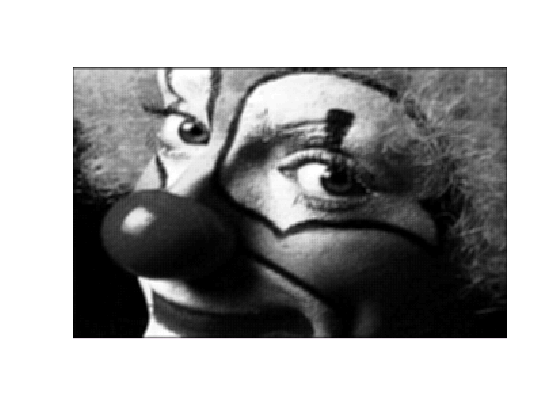

kernel = (1/9) * ones(3);
A = opConvolve(m, n, kernel, [2, 2], 'truncated');

x = X(:);
y = A * x;
Y = reshape(y, m, n);
plotimage(Y);

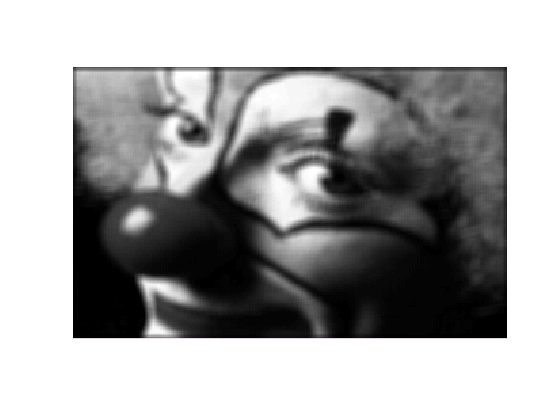

kernel = (1/49) * ones(7);
A = opConvolve(m, n, kernel, [4, 4], 'truncated');

y = A * x;
Y = reshape(y, m, n);
plotimage(Y);

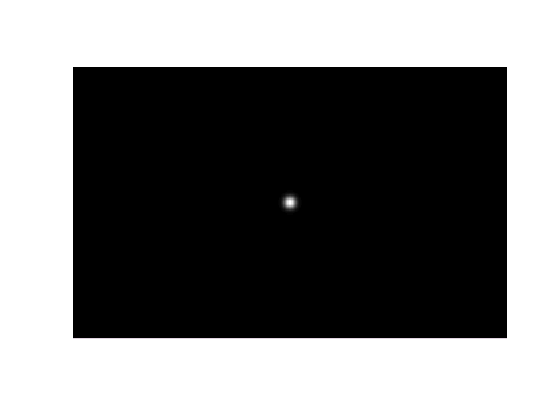

[K, center] = psfGaussian(m, n, 3);
[K2, center2] = psfGaussian(m, n, 6);
plotimage(K);

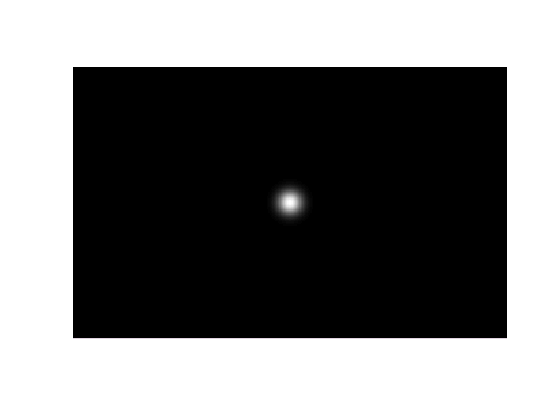

plotimage(K2);

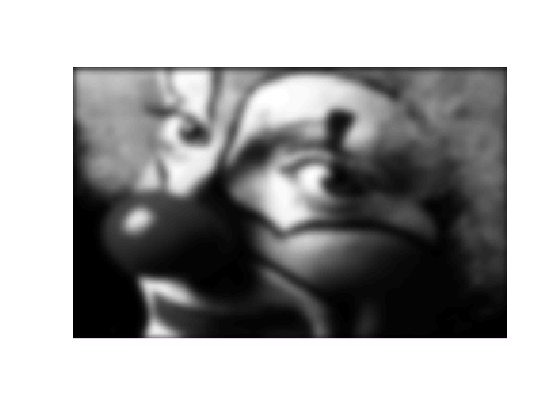

A = opConvolve(m, n, K, center, 'truncated');
y = A * x;
Y = reshape(y, m, n);
plotimage(Y);

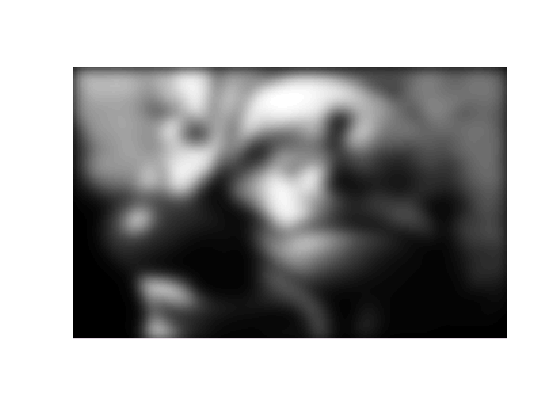

A = opConvolve(m, n, K2, center2, 'truncated');
y = A * x;
Y = reshape(y, m, n);
plotimage(Y);

z = A \ y;
Z = reshape(z, m, n);
plotimage(Y);

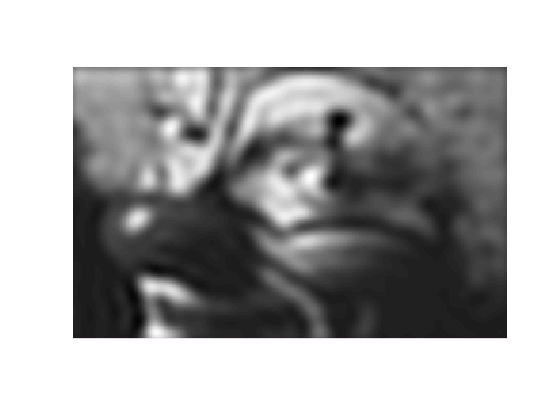

plotimage(Z);

AI = [A; 0.1 * opEye(N)];
y0 = [y; zeros(N,1)];
z = AI \ y0;
Z = reshape(z, m, n);
plotimage(Y);

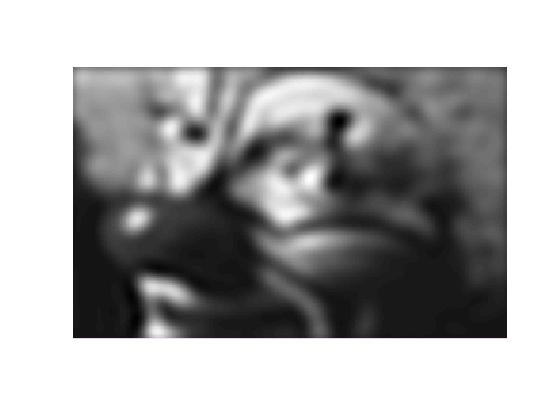

plotimage(Z);

**(d)**

For **(c)** (implementation of conjugate gradient for normal equations), see the end of the document.

Residual after 5 iterations: 1.629723e+02


Residual after 10 iterations: 6.780013e+01


Residual after 50 iterations: 1.050076e+01


Residual after 100 iterations: 4.741851e+00


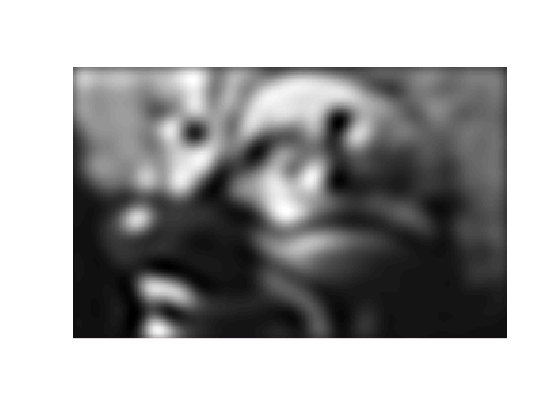

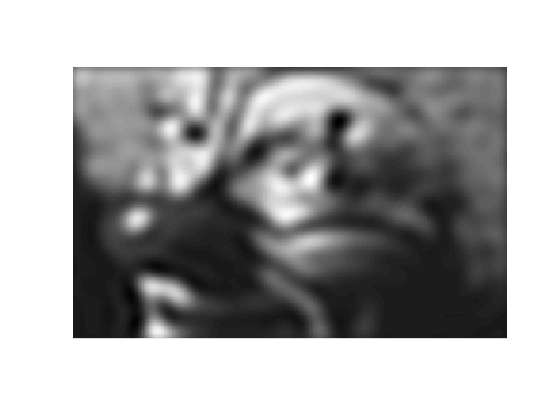

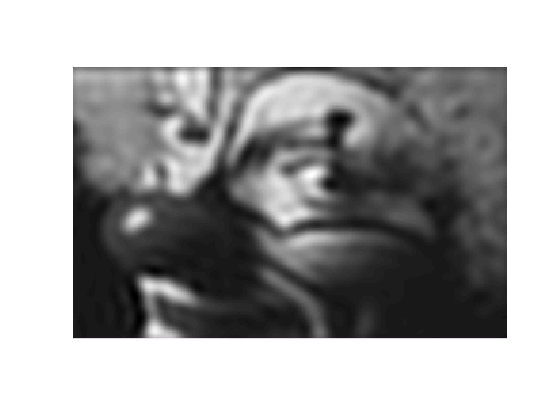

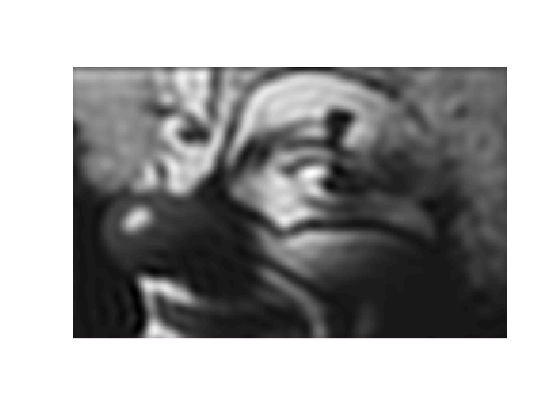

for i = [5, 10, 50, 100]
    z = conjugateGradient(A, y, i);
    Z = reshape(z, m, n);
    figure;
    plotimage(Z);
    fprintf('Residual after %d iterations: %e\n', i, norm(y - A*z));
end

% Conjugate gradient algorithm for the normal equations
%
% Parameters:    an n-by-n matrix A,
%                a right-hand side n-vector b, and
%                the number of iterations to perform
%
% Returns:       an approximate solution n-vector

function x = conjugateGradient(A, b, its)
    B = A' * A;
    c = A' * b;
    
    x = zeros(size(B, 1), 1);
    g = B*x - c;
    p = -g;
    
    for i = 1:its
       a = -dot(p, g) / dot(p, B*p);
       x = x + a * p;
       g = B*x - c;
       gamma = dot(g, B*p) / dot(p, B*p);
       p = -g + gamma * p;
    end
end